# Creating a EEG Cleaning User-defined Function

In this livescript, we will create a user-defined function to preprocess our data (resample, apply a bandpass filter, re-reference data, apply ASR, and perform ICA). This will be a more interactive tutorial where you have to write the code for these processes; you have the resources in the previous tutorials to do so. We can also go through it together if you are unsure of some sections. 

Before we begin, we will create a dependencies folder in our local directory where this Live Script is located. This will serve as our folder to store any user-defined functions we write.

% Dependencies Folder
dir_dep = 'dependencies';

%Creating a directory/folder called dependencies:
%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_dep))
    fprintf('Creating a new folder at %s',dir_dep);
    mkdir(dir_dep); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_dep)
end

dependencies already exists!

## User-defined Functions

Functions let you perform a specific task. User-defined functions are functions created by the user according to their needs. You can write a script to preprocess your data, but functions provide more flexibility as you can use them in any scripts. Rather than copying and pasting your preprocessing pipeline in different scripts, you can insert one function to preprocess them. Modifying functions is also fairly easy. They provide a way to standardize your preprocessing pipeline if you clean your data the same way for different experiments. 

Let's look at a simple user defined function (in the **Example User Defined Functions **at the end of this LiveScript) to calculate the area of a circle given a radius: 

%Calculating area of circle with radius of 3 
rad = 3;
a = area_circle(rad);
fprintf('The area of the circle with radius %i is %.3f',rad,a);

The area of the circle with radius 3 is 28.274

It seems pretty simple so far. To create a function, we use the **function **keyword (see area_circle function at last section of LiveScript). Next, we write the **output argument** which is area. The next part is like an equation to get the output where we write our **function name **(area_circle) and **input argument** (rad) surrouinded by parenthesis. While this a simple function, it is good practice to write a description for our function, documenting what it does, what inputs it takes, the output it spits out, and any revisions you have done. I got this template from [here](https://www.mathworks.com/help/simulink/mdl_gd/hi/matlab-functions.html#btolvhf-1).

You will notice that we used our function before actually defining our function. This is one way of storing your function: including them at the end of your script, but we usually store functions in its own file (which we will do for our preprocessing EEG function). The name of the file has to be the same as your function name.

## Inputs and Input Parser

One thing that might complicate matters is the use of required AND optional inputs. As we saw above, the area_circle function requires the input radius to work. You can add more required inputs this way, but how do we add optional inputs with default values?

We can add more optional inputs in our user-defined function by adding the **varargin **input variable in the same way we can add required inputs (e.g. function outPut = exampleFun(requiredInput,varargin)...) . This special input variable enables the function to accept any number of input arguments. When the function executes, the varargin is a 1-by-N cell array, where N is the number of inputs that the function receives after the *explicitly declared inputs (or required inputs*)*. *If the function receives no optional inputs, then the varargin is an empty cell array. We can look at a function that uses this; we worked with pop_runica when applying ICA to an EEG dataset (See below). In the pop_runica, EEG is a required input, but the other 'runica' and 'extended' inputs are optional inputs. Moreover, notice that we explicitly name (icatype or extended) the input before stating what we want to define it as ('runica' and 1). We don't explicitly define or type varargin when using the function; it is implied that everything after the the required input is part of varargin.

%DO NOT RUN! IT IS AN EXAMPLE OF OPTIONAL INPUTS
% EEG = pop_runica(EEG,'icatype','runica','extended',1);

Okay. So we know how to add optional inputs in our function, but how do we access them in the function and how do we add default values for them? 

This is where an **inputParser** object comes in. This object allows you to manage inputs to a function by creating an input parser scheme. Rather than explaining, it might be better to show you how an input parser works with the eeg preprocessing function you will finish writing (called **preprocess_eeg**). I have written out your documentation and have initiated the input parser, so please REVIEW THE CODE BELOW at the end in the **Example User Defined Functions **before continuing. 

To create an input parser, we need to initiate it with the input_parser function (Line 205), which we call **ip in preprocess_eeg**. We define an function name for our input parser (Line 206). In the preprocess_eeg function, we have one required input: eegIn, the EEG struct we want to preprocess. We add a required input by using the **inputParser.addRequired** function (Line 209; ip.addRequired). It can take up two arguments: the name of required input as a string and a verification function (@isstruct). While the name is self-explanatory, the verification function checks if the required input is a struct. If it isn't a struct, it will spit out an error. 

To add optional arguments, we use the **input_parser.addOptional **function (lines 213-265; ip.addOptional). It can take up to three arguments: the name of optional input, its default value, and a verification function. We don't necessarily need the verification function, so you might see some of these optional functions without it. For instance, we have to logical optional inputs: **perform_asr** and **perform_ica**. We check if these are logical/boolean inputs. These specific inputs are used if the user wants to perform ASR or ICA, respectively. You can see familiar inputs that you saw from previous tutorials. Refer to these optional arguments as they will help you in completing the function. 

Finally, you can parse your required and optional argument using the **parse** function (Line 268) that takes in the input parser, the required input(s), and varargin{:} for our optional arguments. With the inputs parsed out, we can access our inputs using the inputParser object (defined as ip), which is a struct. We use the **Results** field name to do this in our ip struct. To access the resample_srate optional argument in our function, we use the **ip.Results.resample_srate**. I have written the resampling part of this function (see Line 271), so please review it. **Remember that from that part onwards, you will use eegOut as your input/output for the rest of your EEGLAB preprocessing functions**. You can access other optional arguments like bandpass_range or thresh_asr within the function in very much the same way (ip.Results.bandpass_range or ip.Results.thresh_asr). 

In the following interactive exercises, we will need to access these optional inputs to perform the desired preprocessing (e.g. bandpass or ICA).

## Interactive Exercise: FINISHING THE preprocess_eeg FUNCTION

We have an unfinished preprocess_eeg function at the end of this LiveScript. Your task is to finish writing it. In this function, the EEG will be resampled, **a bandpass filter is appled to it**, **it is re-referenced**, ** ASR is performed on it**, and finally** ICA is performed on it**. As you have seen in the previous section, I haved resample our input EEG data (eegIn) to 250 Hz, so your job is to finish the code by applying a bandpass filter, rereferencing the EEG, performing ASR, and performing ICA (all of which is separated by comments and if statements). To complete this, I would recommend going to previous tutorials to reference and modify/copy the code. **However,** **we need to do some things before starting/completing this exercise:** 

- In the **dependencies **directory, create a new Matlab function file. Click on the dependencies folder in your Current Folder menu to navigate into it. If you are in the LIVE EDITOR Tab (above), click on the "New" drop down menu and choose function, naming it **preprocess_eeg**. 

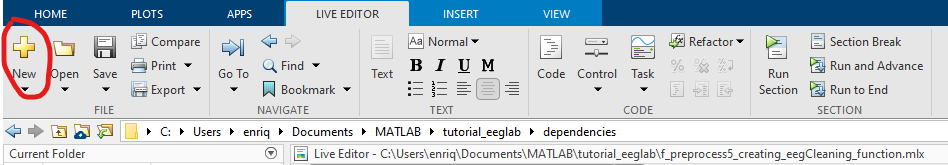

- Open this new preprocess_eeg file (just double click it) and it should open a new window with default text; just delete that text as we don't need it! Copy/Cut and Paste the preprocess_eeg function at the end of this LiveScript into that new file (preprocess_eeg). **Please comment out the preprocess_eeg function at the end of this LiveScript after doing this!**

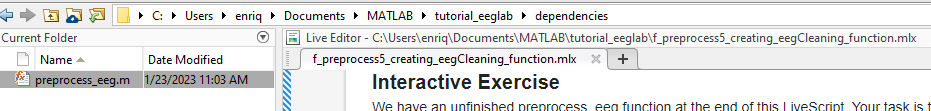

- Finally, navigate back to where this livescript is by hitting the left arrow (or back button) next to your path. 

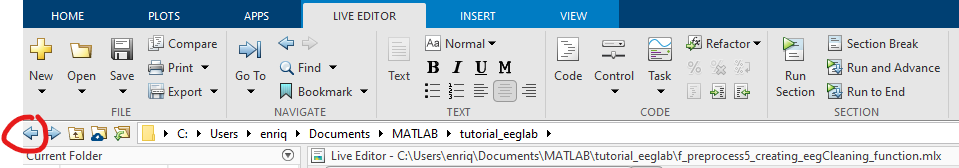

With your preprocess_eeg function file open in your MATLAB editor, complete the function. Remember that your inputs are accessed via the input parser (e.g. ip.Results.reference_chan), so review the last section carefully. 

## Preprocessing using Your Function

If you have done things correctly, we can finally preprocess our data, so let's load in our raw data and use your function. 

% Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
eeglab;

%Directory where are data are located: 
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located: 
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located: 
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data: 
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

%Channels We Want to Remove which include external channels and trigger:
rmCh_labels = {...
    'Trig1','EX1','EX2','EX3','EX4','EX5','EX6','EX7','EX8'...
    };

Format specifier for our recording: 
file_spec = 'vrcct_%s_%s_%s.%s'; %Four char formatting operators

%Let us define the name parts of our file: 
sub = 'p16'; %subject or participant 16
study = 'prestudy'; %First session of experiment
part = 'condition'; %meditation part of session
ext = 'xdf'; %File extension of our dataset (LSL recording)

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Loading LSL recording: 
EEG = pop_loadxdf( ...
    fullfile(dir_xdf,file_name));

% Removing non-EEG channels:
EEG = pop_select(EEG, 'nochannel', rmCh_labels);

%Loading in Channel information:
EEG = pop_chanedit( ...
    EEG, ...
    'load',fullfile(dir_head,'bio_semi_64.ced'));

%Re-centering channel locations: 
EEG = pop_chanedit( ...
    EEG, ...
    'eval','chans = pop_chancenter( chans, [],[]);');

We can finally use your function to preprocess the loaded dataset. Just make sure to uncoment the parts indicated in the next code block. Also take note that to use this user-defined function, we had to load in our channel information! 

% Adding dependencies directory to use our function (that's where our
% function is located)
addpath('dependencies')

% Displaying function information (UNCOMMENT IT; remove % in front of it)
%help preprocess_eeg

%FINALLY USING YOUR FUNCTION! (UNCOMMENT IT; remove % in front of it)
%EEG_clean = preprocess_eeg(EEG);

%DIFFERENT EXAMPLES ON HOW TO USE IT (you don't have to uncomment these): 

%With no ASR: 
% ECG_clean = preprocess_eeg(EEG,'perform_asr',false);

%With no ICA:
% ECG_clean = preprocess_eeg(EEG,'perform_ica',false);

%Changing multiple parameters: 
% ECG_clean = preprocess_eeg( ...
%     EEG, ...
%     'bandpass_range',[1,20], ...
%     'thresh_poorCorrChannel',0.80, ...
%     'thresh_asr',3);

## Conclusion

We have successfully created a function to preprocess our EEG. Rather than copying and pasting our preprocessing pipeline, we have created a function we can call to in any script (after adding dependencies to your path) to preprocess any raw EEG dataset. You can modify that function in any way you can to fit your research needs. What can we use with this function? We can batch process many files now with a for-loop, which we will perform in the next tutorial. 

## Example User Defined Functions

function [area] = area_circle(rad,varargin)
    %{
FUNCTION NAME: 
    area_circle

DESCRIPTION: 
    Compute area of a circle given the radius

INPUT: 
    rad - (double) Radius of the circle 

OUTPUT: 
    area - (double) Calculated area of a circle using given radius

ASSUMPTIONS AND LIMITATIONS:
    None

REVISION HISTORY:
    01/20/2023 - enrique
        * Initial implementation
    %}

    %Calculating area of circle
    area = pi*(rad^2);

end

**PLEASE COMMENT ME OUT AFTER COPYING/PASTING ME IN A NEW FUNCTION FILE LOCATED IN THE DEPENDENCIES DIRECTORY!!!**

function eegOut = preprocess_eeg(eegIn,varargin)

% FUNCTION NAME: 
%     preprocess_eeg
% 
% DESCRIPTION: 
%     Preprocess EEG pipeline with resampling, bandpass filter, re-referencing, optional
%     ASR application, and optional ICA. 
% 
% REQUIRED INPUT: 
%     eegIn - (struct) EEG struct loaded in with EEGLAB 
% 
% OPTIONAL INPUT: 
%     resample_srate = (integer) sampling rate in Hz to resample to; default 
%         to 250 Hz
%     bandpass_range - (vector with two values) bandpass range in Hz;
%         defaults to [1,50]
%     reference_chan - (cell array with reference channel labels e.g.
%         {'M1','M2'}) Reference channels you want to rereference your data;
%         defaults to {} for an average reference
%     perform_asr - (Logical) Logical flag to perform ASR. If False, it will
%         not perform ASR; defaults to True to perform ASR
%     thresh_flatChannel - (double) Maximum tolerated flatline duration in
%         seconds. If a channel has a longer flatline than this value, it
%         will be considered abnormal and removed; defaults to 5 seconds
%     highPass_band - (vector with two values) Transition band for the
%         initial high-pass filter in Hz. This is formatted as
%         [transition-start,transition-end]; defaults to -1 to disable it
%     thresh_poorCorrChannel - (double ranging from 0 to 1) Minimum channel correlation. 
%         If channel iscorrelated at less than this value to a reconstruction of it based
%         on other channels, it is considered abnormal in the given time
%         window and removed. This method requires that channel locations are
%         available and roughly correct; defaults to 0.70
%     thresh_lineNoise - (double) If a channel has more line noise relative
%         to its signal than this value in standard deviation units, it is
%         considered abnormal and removed; defaults to 4
%     thresh_asr - (integer) Standard deviation cutoff for removal of bursts
%         noise via ASR. Data portions whose variance is larger than this
%         threshold relative to the calibration data are considered missing
%         data and will be removed. The most aggressive value that can be
%         used without losing too much EEG is 3. For new users, it is
%         recommended to at first visuall inspect the difference between the
%         difference between the original and cleaned data to get a sense of
%         the removed content at various levels. An aggressive value is 5 and
%         a quite conservative value is 20; defaults to 20. artifact
%         subspace reconstruction
%     thresh_window - (double) Criterion for removing time windows that were
%         not repaired completely. This may happen if the artifact in a
%         window was composed of too many simultaneous uncorrelated sources
%         (e.g. extreme movements such as jumps). This is the maximum
%         fraction of contaminated channels that are tolerated in the final
%         output for each considered window. Generall a lower value makes the
%         criterion more aggressive; defaults to -1 to disable it, but the
%         clean_rawdata function defaults to 0.25. Reasonable range: 0.05
%         (very aggressive) to 0.3 (very lax). 
%     perform_ica - (Logical) Logical flag to perform ICA. If False, it will
%         not perform ICA; defaults to True to perform ICA
%     thresh_ica_artifacts - (7x2 matrix array) probability thresholds to
%         include selection as artifacts. The seven artifact categories that
%         each row represents are BRAIN, EYE, HEART, LINE NOISE, CHANNEL
%         NOISE, AND OTHER; defaults to 
%         [NaN,NaN;0.8,1.0;0.8,1.0;0.8,1.0;0.8,1.0;0.8,1.0;NaN,NaN]
%     
% 
% OUTPUT: 
%     eegOut - (struct) clean ECG data
%
% EXAMPLES: 
%   %With no ASR: 
%       ECG_clean = preprocess_eeg(EEG,'perform_asr',false);
%
%   %With no ICA:
%       ECG_clean = preprocess_eeg(EEG,'perform_ica',false);
%
%   %Changing multiple parameters: 
%       ECG_clean = preprocess_eeg( ...
%           EEG, ...
%           'bandpass_range',[1,20], ...
%           'thresh_poorCorrChannel',0.80, ...
%           'thresh_asr',3);
% 
% ASSUMPTIONS AND LIMITATIONS:
%     None
% 
% REVISION HISTORY:
%     01/20/2023 - enrique
%         * Initial implementation

%Input Parser: 
ip = inputParser;
ip.FunctionName = 'preprocess_eeg';

%Required Input: 
ip.addRequired('eegIn',@isstruct);

%Optional Inputs with Default values:

% Resampling sampling rate that defaults to 250Hz
ip.addOptional('resample_srate',250);

%Bandpass Range with default of 1 to 50Hz; 
%  The input parser will check if it is a vector: 
ip.addOptional('bandpass_range',[1,50],@isvector);

%Reference Channel with default of empty array;
% The input parser will check if it is a cell array
ip.addOptional('reference_chan',{},@iscell);

%These optional inputs will be for ASR

%Indicator to peform ASR deafulated to True; 
% If False, the function will not perform ASR
ip.addOptional('perform_asr',true,@islogical)

%Threshold for Flat Line Channel with default 5
ip.addOptional('thresh_flatChannel',5);

%Bandpass filter that is disabled by default (-1):
ip.addOptional('highPass_band',-1);

%Threshold for poor channel correlation with default of 0.7:
ip.addOptional('thresh_poorCorrChannel',0.7);

%Threshold for Line Noise in channel with default of 4:
ip.addOptional('thresh_lineNoise',4);

%Threshold for removal of burst via ASR with default of 4:
ip.addOptional('thresh_asr',20);

%Threshold of window size to remove, but is disabled (-1):
ip.addOptional('thresh_window',-1);

% These optional inputs will be for ICA

%Indicator to peform ICA deafulated to True; 
% If False, the function will not perform ICA
ip.addOptional('perform_ica',true,@islogical)

%Artifact Probability Thresholds
thresh_artifacts = [
    NaN, NaN; % Brain
    0.8, 1.0; % Muscle
    0.8, 1.0; % Eye
    0.8, 1.0; % Heart
    0.8, 1.0; % Line Noise
    0.8, 1.0; % Channel Noise
    NaN, NaN]; % Other

%Artifact probability thresholds for ICA:
ip.addOptional('thresh_ica_artifacts',thresh_artifacts);

%Parsing out arguments:
parse(ip,eegIn,varargin{:});

%Resampling eeg data
eegOut = pop_resample(eegIn,ip.Results.resample_srate);

%APPLY A BANDPASS FILTER: (REMEMBER TO USE eegOut as an input from now on!)


%RE-REFERENCE EEG DATA


%PERFORM ASR HERE
if ip.Results.perform_asr

    %WRITE CODE HERE

end

%PERFORM ICA HERE
if ip.Results.perform_ica
    
    %WRITE CODE HERE

end


%END OF FUNCTION
end